## **Soft beam free fall** 

We created a 0.5m soft beam with radius linearly varying from 2cm to 1cm.

Torsion (x-axis) and bending (y- and z-axis) modes of deformation are enabled with a cubic strain.

SorosimLink (`L1`) and SorosimLinkage (`T1`) saved in `FreeFall.mat`

load('FreeFall.mat')

To see the properties of `L1`

L1

To see the properties of S`1`

T1

To see the problem definition:

T1.plotq0

The result should be:

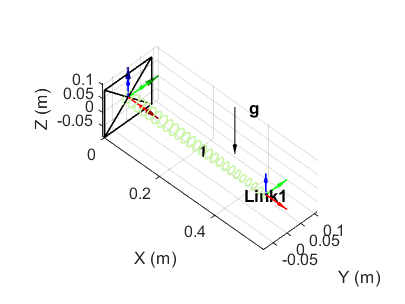

The beam is rigidly fixed at one end and subjected to gravity.

### **Static equilibirum analysis**

For statics equilibirum analysis type:

q=T1.statics;

A dialog box will pop up, asking for the initial guess. The user can choose the default value.

The equilibirum solution is,

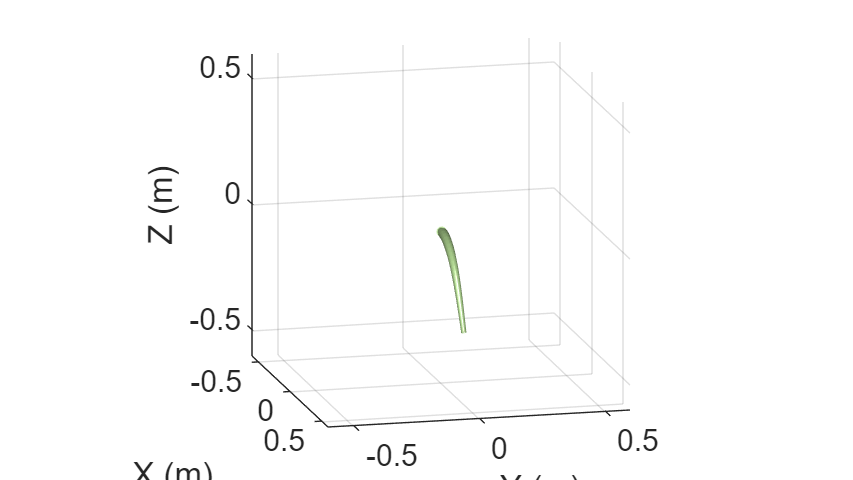

### **Damped dynamics**

For dynamics problem, type:

[t,qqd]=T1.dynamics([],'ode15s');

Initial conditions of state coordinates ($$\mathbf{q_0}$$) and their derivatives ($$\mathbf{\dot{q_0}}$$) will be asked in a dialog box. The user can also choose the time for which the simulation is run (the default value is 5 s).

Another dialog box will appear, asking the user if he/she wants to see a plot during the dynamic compulation. (this is slow and will not work in live script)

Dynamic compulation will take some time.

The results of the dynamic simulation (`t` and `qqd`) will be saved in `DynamicsSolution.mat `in the folder from which the simulation is run.

At the end of simulation, in the dialog box that appear, choose to generate the video if needed.  This step will also take some time. 

A video named `Dynamics.avi` will be saved in the folder.

Energy computations can be made by running energy.m after the dynamic simulation is complete

energy

### **Undamped dynamics**

To turn off the elastic damping of the system type:

T1.Damped=false;

We run the dynamic simulation again

[t,qqd]=T1.dynamics([],'ode113');
energy